L = 0.127

L = 0.1270



v_a1 = -180:0.5:180;
v_a2 = 0:0.5:360;

access_adm = [];
a1_adm = [];
a2_adm = [];
p1_adm = [];

a1_err = [];
a2_err = [];
p1_err = [];

a1_imp = [];
a2_imp = [];
p1_imp = [];
for i = 1:size(v_a1,2)
    for j = 1:size(v_a2,2)
        a1 = deg2rad(v_a1(i));
        a2 = deg2rad(v_a2(j));
        
        [x, y, p1 , p2, error] = direct_kinematics(a1,a2);
        a2 = a2-pi/2;
        if error == 0
            lambda_v = vel_jacobian(a1,a2+pi/2,p1,p2);
            lambda_v = normalize_columns(lambda_v);
            access_adm(end+1) = 1-det(lambda_v*lambda_v');
            a1_adm(end+1) = a1;
            a2_adm(end+1) = a2;
            p1_adm(end+1) = p1;
        elseif not(isnan(p1))
            a1_err(end+1) = a1;
            a2_err(end+1) = a2;
            p1_err(end+1) = p1;
        else
            a1_imp(end+1) = a1;
            a2_imp(end+1) = a2;
            p1_imp(end+1) = -1;
        end

    end
end


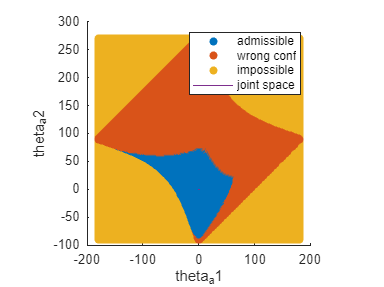

a1_adm = rad2deg(a1_adm);
a2_adm = rad2deg(a2_adm);

a2_err = rad2deg(a2_err);
a1_err = rad2deg(a1_err);

a1_imp = rad2deg(a1_imp);
a2_imp = rad2deg(a2_imp);



figure
hold on
scatter3(a1_adm,a2_adm,p1_adm,'filled')
scatter3(a1_err,a2_err,p1_err,"filled")
scatter3(a1_imp,a2_imp,p1_imp,"filled")
plot3( deg2rad([-17 31 31 -17 -17]), deg2rad([-27 -27 27 27 -27]), [10 10 10 10 10] )

xlabel("theta_a1")
ylabel("theta_a2")
% rectangle('Position',deg2rad([-17 -27 31 27]))
legend(["admissible","wrong conf","impossible","joint space"])
daspect([1 1 0.1])
hold off

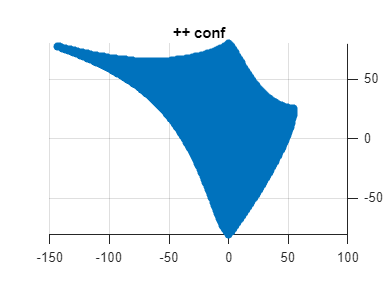

figure
scatter3(a1_adm,a2_adm,access_adm,'filled')
daspect([1 1 1])
title("++ conf")
view([0.65 90.00])

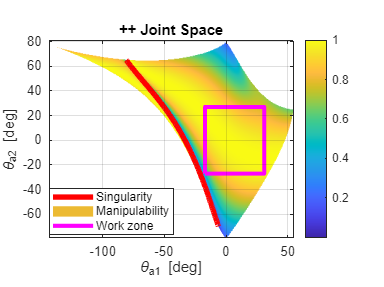

delta_theta = 0.5;
v_a1 = min(a1_adm):delta_theta:max(a1_adm);
v_a2 = min(a2_adm+pi/2):delta_theta:max(a2_adm+pi/2);
[m_a1,m_a2] = meshgrid(v_a1,v_a2);
acc = zeros(size(v_a2,2),size(v_a1,2));
detJ = zeros(size(v_a2,2),size(v_a1,2));



for  i = 1:size(v_a1,2)
    for j = 1:size(v_a2,2)
        a1 = deg2rad(v_a1(i));
        a2 = deg2rad(v_a2(j))+pi/2;
        [~, ~, p1 , p2, error] = direct_kinematics(a1,a2);
        if error == 0
            lambda_v = vel_jacobian(a1,a2,p1,p2);
            lambda_v = normalize_columns(lambda_v);
            acc(j,i) = clamp(sqrt(det(lambda_v*lambda_v')),1);
            detJ(j,i) = det(lambda_v);
            
        else
            detJ(j,i) = NaN;
            acc(j,i) = NaN;
        end
        % v_a2(j) = v_a2(j)-pi/2;
        % [A1(j,i),A2(j,i),P1(j,i),P2(j,i),D(j,i),D_v(j,i),O(j,i),RGA(j,i),~,~,~,~,ME(j,i)] = get_q(v_x(i), v_y(j),false);
        
    end
end
% m_a2 = rad2deg(m_a2)-90;
% m_a1 = rad2deg(m_a1);

contour3(m_a1,m_a2,detJ+1,[1 1],"r","LineWidth",4);
hold on

s = surf(m_a1,m_a2,acc);

s.EdgeColor = 'none';
xlabel("\theta_{a1} [deg]")
ylabel("\theta_{a2} [deg]")

plot3( [-17 31 31 -17 -17] ,[-27 -27 27 27 -27], 1*[1 1 1 1 1],"-m" ,"LineWidth",3)
daspect([1 1 0.01])
% rectangle('Position',deg2rad([-17 90-27 31+17 +27*2]))
legend(["Singularity","Manipulability","Work zone"],"Position", [0.1499 0.1920 0.2814, 0.1421])
view([0 90.00])
colorbar
title("++ Joint Space")
hold off